Erdem KÖSE

# TEL608-Spectral Estimation Methods Final Project

In this project I will inspect the popular spectral estimation methods with audio file consists G5 note with trumpet. Each of models will be shown in whole and short-time structure. My personal favorite is Min-Norm method, because it gives Autoregressive parameters and a good Power Spectral Density at the same time.

## Data Load

clear; clc; close all;

[x,fs]=audioread('trumpet-G5.wav');
N=size(x,1);
d=size(x,2);
t=fs*((1:N)-1)';

xzm=x-mean(x,1);

x_channel_labels=cell(d,1);
for i=1:d
    x_channel_labels{i}=['Channel ' num2str(i)];
end

#### Short-time Partitioning


$$\begin{array}{l}
N_{\textrm{partition}} =\textrm{ceil}\left(\frac{N}{\textrm{Partition}\;\textrm{Count}}\right),N_{\textrm{new}} =\textrm{Partition}\;\textrm{Count}*N_{\textrm{partition}} \\
x_{\textrm{new}} =\left\lbrack \begin{array}{cc}
x & \textrm{zerox}\left(N_{\textrm{new}} -N,d\right)
\end{array}\right\rbrack \\
x_{\textrm{shorttime}} =\textrm{reshape}\left(x,\left\lbrack N_{\textrm{partition}} ,\textrm{Partition}\;\textrm{Count}\right\rbrack \right)
\end{array}$$


partition_count=500;
partition_N=ceil(N/partition_count);
Nnew=partition_count*partition_N;
x_st=[x; zeros(Nnew-N,d)];
x_st=reshape(x_st,[partition_N,partition_count]);
x_st=x_st-mean(x_st,1);

x_stax = [0 Nnew/fs]; %t axis
y_stax = [0 fs/2]; %f axis

#### Plot Time Series

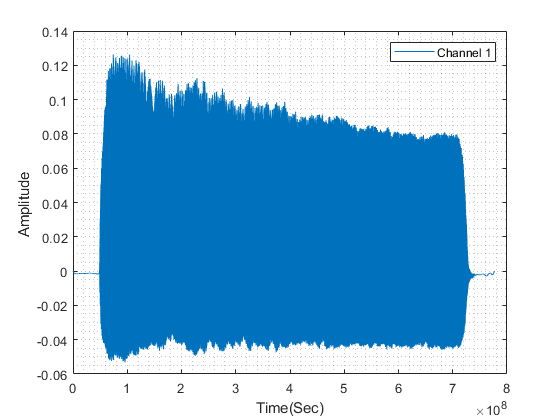

plot(t,x)
ylabel('Amplitude ');
xlabel('Time(Sec)');
legend(x_channel_labels)
grid minor;

## Spectral Estimation Library

spestm_obj=spestm_lib();
spestm_obj.f_range='half';
spestm_obj.window_type='hann';
spestm_obj.x=xzm;
%spestm_obj.x=spestm_obj.side_awgn(20);
spestm_obj.fs=fs;
spestm_obj.p=24;
spestm_obj.q=4;
spestm_obj.M=96;
spestm_obj=spestm_obj.init();

spestm_obj_st=spestm_lib();
spestm_obj_st.f_range='half';
spestm_obj_st.window_type='hann';
spestm_obj_st.x=x_st;
spestm_obj_st.x=spestm_obj_st.side_awgn(20);
spestm_obj_st.fs=fs;
spestm_obj_st.p=12;
spestm_obj_st.q=2;
spestm_obj_st.M=24;
spestm_obj_st=spestm_obj_st.init();

### Periodogram PSD

The most basic one is Periodogram, it's just amplitude spectrum of autocorrelation function $r_X \left\lbrack k\right\rbrack$'s Fouirer transform.


$$x_w \left\lbrack n\right\rbrack =w\left\lbrack n\right\rbrack x\left\lbrack n\right\rbrack$$



$$r_X \left\lbrack k\right\rbrack =\frac{1}{f_{s\;} }\sum_{n=0}^{N-1} x_w \left\lbrack n\right\rbrack \bar{x_w } \left\lbrack n-k\right\rbrack$$



$$P_X^{\textrm{per}} \left(f\right)=\left|\;\sum_{k=0}^{N-1} r_X \left\lbrack k\right\rbrack e^{-\textrm{j2}\pi \frac{f}{f_s }n} \right|$$


[y_per,f]=spestm_obj.psd_periodogram();
y_per_st=spestm_obj_st.psd_periodogram();

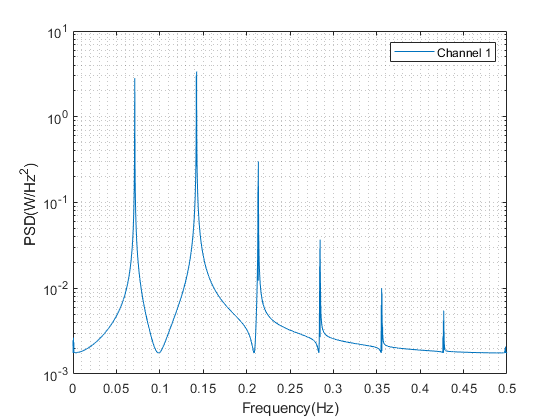

semilogy(f,y_per);
ylabel('PSD(W/Hz^2) ');
xlabel('Frequency(Hz)');
legend(x_channel_labels)
grid minor;

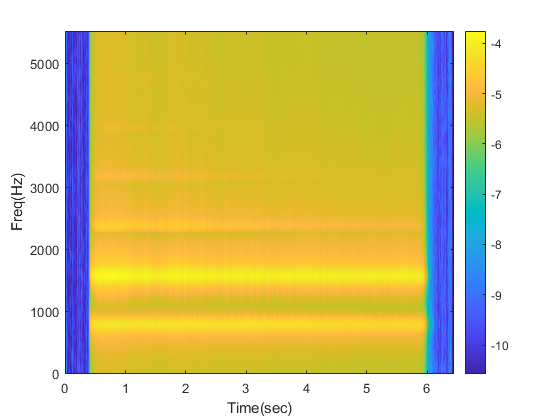

image_y=log10(y_per_st);
imagesc(x_stax,y_stax,image_y)
caxis([min(min(image_y)) max(max(image_y))]);
xlabel('Time(sec)')
ylabel('Freq(Hz)')
set(gca,'YDir','normal')
colorbar;

### Blackman-Tukey PSD

It's the variant of Periodogram, but differs in windowing. We window $R_X \left\lbrack k\right\rbrack$ instead of $x\left\lbrack n\right\rbrack$.


$$r_X \left\lbrack k\right\rbrack =\frac{1}{f_{s\;} }\sum_{n=0}^{N-1} x\left\lbrack n\right\rbrack \bar{x} \left\lbrack n-k\right\rbrack$$



$$r_{X_w } \left\lbrack k\right\rbrack =w\left\lbrack k\right\rbrack R_X \left\lbrack k\right\rbrack$$



$$P_X^{\textrm{bt}} \left(f\right)=\left|\;\sum_{k=0}^{N-1} r_{X_w } \left\lbrack k\right\rbrack e^{-\textrm{j2}\pi \frac{f}{f_s }n} \right|$$


[y_bt,f]=spestm_obj.psd_blackmantukey();
y_bt_st=spestm_obj_st.psd_blackmantukey();

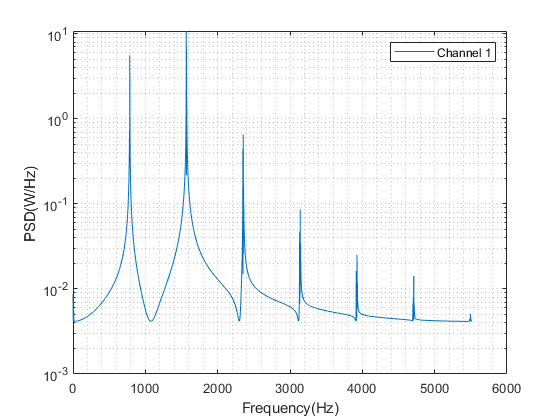

semilogy(f,y_bt);
ylabel('PSD(W/Hz) ');
xlabel('Frequency(Hz)');
legend(x_channel_labels)
grid minor;

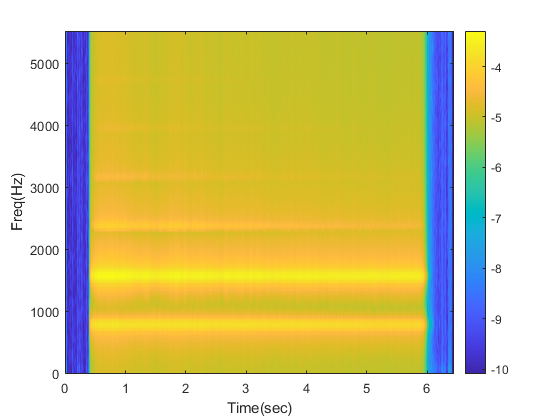

image_y=log10(y_bt_st);
imagesc(x_stax,y_stax,image_y)
caxis([min(min(image_y)) max(max(image_y))]);
xlabel('Time(sec)')
ylabel('Freq(Hz)')
set(gca,'YDir','normal')
colorbar;

### Capon PSD

From now on, we don't mention about windowing. We will use input signal directly. Capon PSD, is one of the best because of detail parameter $g$. If $g$ increases, details of noisy input signal can be observed clearly; but it has a limit naturally.


$$r_X \left\lbrack k\right\rbrack =\frac{1}{f_{s\;} }\sum_{n=0}^{N-1} x\left\lbrack n\right\rbrack \bar{x} \left\lbrack n-k\right\rbrack$$



$$R_X =\left\lbrack \begin{array}{cccc}
r_X \left\lbrack 0\right\rbrack  & r_X \left\lbrack -1\right\rbrack  & \cdots  & r_X \left\lbrack -\left(p-1\right)\right\rbrack \\
r_X \left\lbrack 1\right\rbrack  & r_X \left\lbrack 0\right\rbrack  & \cdots  & r_X \left\lbrack -\left(p-2\right)\right\rbrack \\
\vdots  & \vdots  & \ddots  & \vdots \\
r_X \left\lbrack p-1\right\rbrack  & r_X \left\lbrack p-2\right\rbrack  & \cdots  & r_X \left\lbrack 0\right\rbrack 
\end{array}\right\rbrack$$



$${\mathit{\mathbf{e}}}_{\textrm{vect}} ={\left\lbrack \begin{array}{cccc}
1 & e^{-\textrm{j2}\pi f\;}  & \cdots  & e^{-\textrm{j2}\pi f\left(p-1\right)\;} 
\end{array}\right\rbrack }^T$$



$$P_X^{\mathrm{capon}} \left(f\right)=\left|\frac{{\mathit{\mathbf{e}}}_{\mathbf{vect}}^{\mathit{\mathbf{T}}} \left(R_X^{-\left(g-1\right)} \right){\mathit{\mathbf{e}}}_{\mathbf{vect}} }{\;{\mathit{\mathbf{e}}}_{\mathbf{vect}}^{\mathit{\mathbf{T}}} \left(R_X^{-\left(g\right)} \right){\mathit{\mathbf{e}}}_{\mathbf{vect}} }\right|$$


[y_cap,f]=spestm_obj.psd_capon();
y_cap_st=spestm_obj_st.psd_capon();

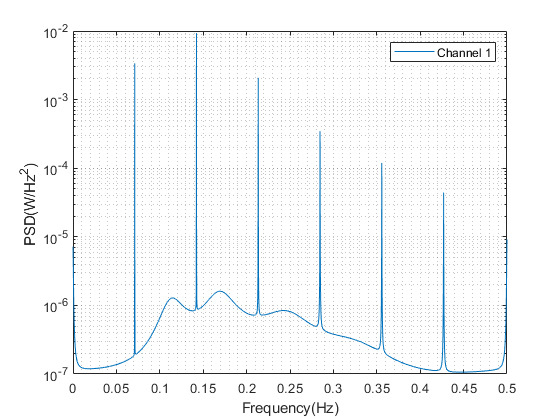

semilogy(f,y_cap);
ylabel('PSD(W/Hz^2) ');
xlabel('Frequency(Hz)');
legend(x_channel_labels)
grid minor;

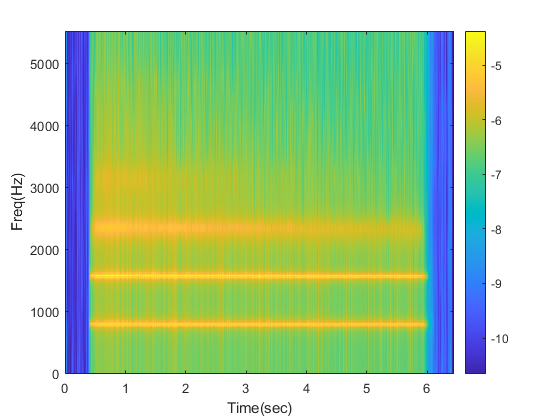

image_y=log10(y_cap_st);
imagesc(x_stax,y_stax,image_y)
caxis([min(min(image_y)) max(max(image_y))]);
xlabel('Time(sec)')
ylabel('Freq(Hz)')
set(gca,'YDir','normal')
colorbar;

### Autoregressive (Yule-Walker) PSD


$$r_X \left\lbrack k\right\rbrack =\frac{1}{f_{s\;} }\sum_{n=0}^{N-1} x\left\lbrack n\right\rbrack \bar{x} \left\lbrack n-k\right\rbrack$$



$$R_X =\left\lbrack \begin{array}{cccc}
r_X \left\lbrack 0\right\rbrack  & r_X \left\lbrack -1\right\rbrack  & \cdots  & r_X \left\lbrack -\left(p-1\right)\right\rbrack \\
r_X \left\lbrack 1\right\rbrack  & r_X \left\lbrack 0\right\rbrack  & \cdots  & r_X \left\lbrack -\left(p-2\right)\right\rbrack \\
\vdots  & \vdots  & \ddots  & \vdots \\
r_X \left\lbrack p-1\right\rbrack  & r_X \left\lbrack p-2\right\rbrack  & \cdots  & r_X \left\lbrack 0\right\rbrack 
\end{array}\right\rbrack$$


Solution of the equation above will give parameter vector $a$.


$$\left\lbrack \begin{array}{cccc}
r_X \left\lbrack 0\right\rbrack  & r_X \left\lbrack -1\right\rbrack  & \cdots  & r_X \left\lbrack -\left(p-1\right)\right\rbrack \\
r_X \left\lbrack 1\right\rbrack  & r_X \left\lbrack 0\right\rbrack  & \cdots  & r_X \left\lbrack -\left(p-2\right)\right\rbrack \\
\vdots  & \vdots  & \ddots  & \vdots \\
r_X \left\lbrack p-1\right\rbrack  & r_X \left\lbrack p-2\right\rbrack  & \cdots  & r_X \left\lbrack 0\right\rbrack 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
a\left\lbrack 1\right\rbrack \\
a\left\lbrack 2\right\rbrack \\
\vdots \\
a\left\lbrack p\right\rbrack 
\end{array}\right\rbrack =-\left\lbrack \begin{array}{c}
r_X \left\lbrack 1\right\rbrack \\
r_X \left\lbrack 2\right\rbrack \\
\vdots \\
r_X \left\lbrack p\right\rbrack 
\end{array}\right\rbrack$$


Parameter $\sigma {\;}^2$ can be obtained by after obtaining parameter vector $\mathit{\mathbf{a}}={\left\lbrack \begin{array}{cccc}
1 & a\left\lbrack 1\right\rbrack  & \cdots  & a\left\lbrack p\right\rbrack 
\end{array}\right\rbrack }^T$


$$\left\lbrack \begin{array}{cccc}
r_X \left\lbrack 0\right\rbrack  & r_X \left\lbrack -1\right\rbrack  & \cdots  & r_X \left\lbrack -\left(p\right)\right\rbrack \\
r_X \left\lbrack 1\right\rbrack  & r_X \left\lbrack 0\right\rbrack  & \cdots  & r_X \left\lbrack -\left(p-1\right)\right\rbrack \\
\vdots  & \vdots  & \ddots  & \vdots \\
r_X \left\lbrack p\right\rbrack  & r_X \left\lbrack p-1\right\rbrack  & \cdots  & r_X \left\lbrack 0\right\rbrack 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
1\\
a\left\lbrack 1\right\rbrack \\
\vdots \\
a\left\lbrack p\right\rbrack 
\end{array}\right\rbrack =-\left\lbrack \begin{array}{c}
\sigma {\;}^2 \\
0\\
\vdots \\
0
\end{array}\right\rbrack$$


Then using these parameters


$$P_X^{\mathrm{ARyw}} \left(f\right)=\frac{\sigma {\;}^2 }{\;\left|{\mathit{\mathbf{e}}}_{\mathbf{vect}}^{\mathit{\mathbf{T}}} \mathit{\mathbf{a}}{\left|\right.}^2 \right.}$$



$${\mathit{\mathbf{e}}}_{\textrm{vect}} ={\left\lbrack \begin{array}{cccc}
1 & e^{-\textrm{j2}\pi f\;}  & \cdots  & e^{-\textrm{j2}\pi \textrm{fp}\;} 
\end{array}\right\rbrack }^T$$
 

[y_aryw,f] = spestm_obj.psd_aryulewalker();
y_aryw_st=spestm_obj_st.psd_aryulewalker();

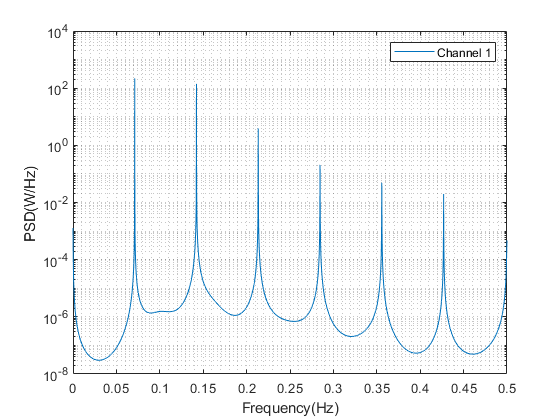

semilogy(f,y_aryw);
ylabel('PSD(W/Hz) ');
xlabel('Frequency(Hz)');
legend(x_channel_labels)
grid minor;

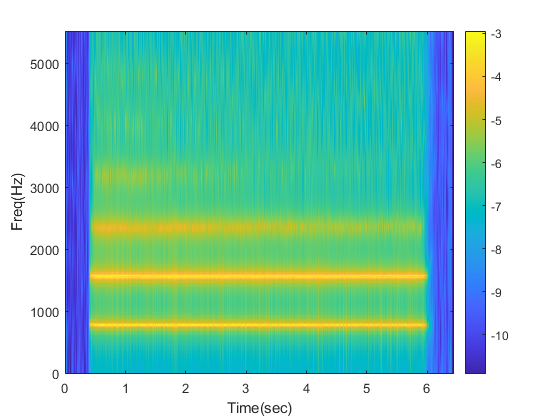

image_y=log10(y_aryw_st);
imagesc(x_stax,y_stax,image_y)
caxis([min(min(image_y)) max(max(image_y))]);
xlabel('Time(sec)')
ylabel('Freq(Hz)')
set(gca,'YDir','normal')
colorbar;

### Autoregressive (Modified Covariance) PSD

[y_armc,f] = spestm_obj.psd_armodcov();
y_armc_st=spestm_obj_st.psd_armodcov();

Rank deficient, p is changed to 0
Rank deficient, p is changed to 0
Rank deficient, p is changed to 0


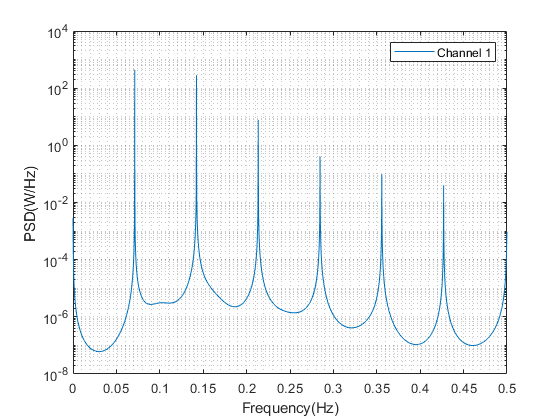

semilogy(f,y_armc);
ylabel('PSD(W/Hz) ');
xlabel('Frequency(Hz)');
legend(x_channel_labels)
grid minor;

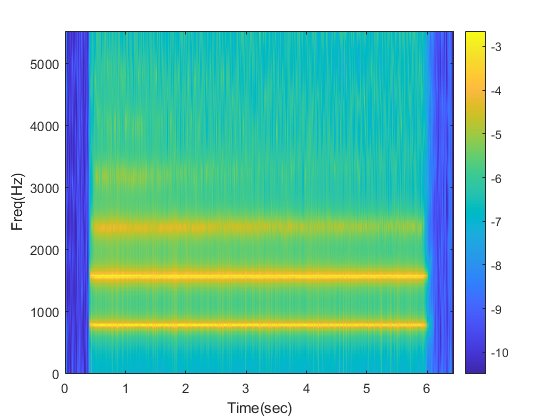

image_y=log10(y_armc_st);
imagesc(x_stax,y_stax,image_y)
caxis([min(min(image_y)) max(max(image_y))]);
xlabel('Time(sec)')
ylabel('Freq(Hz)')
set(gca,'YDir','normal')
colorbar;

### Autoregressive (Burg) PSD

[y_arburg,f]=spestm_obj.psd_arburg();
y_arburg_st=spestm_obj_st.psd_arburg();

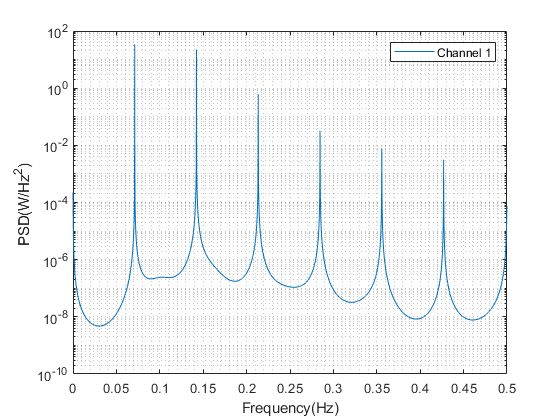

semilogy(f,y_arburg);
ylabel('PSD(W/Hz^2) ');
xlabel('Frequency(Hz)');
legend(x_channel_labels)
grid minor;

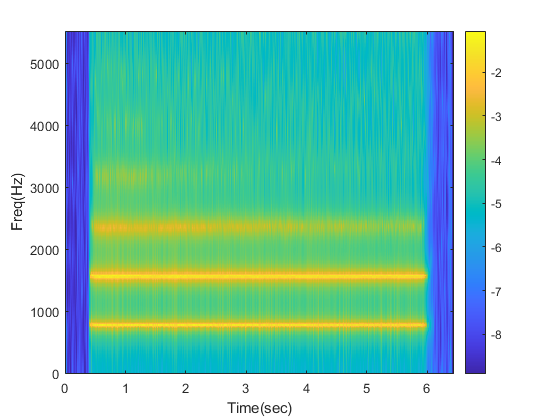

image_y=log10(y_arburg_st);
imagesc(x_stax,y_stax,image_y)
caxis([min(min(image_y)) max(max(image_y))]);
xlabel('Time(sec)')
ylabel('Freq(Hz)')
set(gca,'YDir','normal')
colorbar;

### Autoregressive Moving Average PSD


$$r_X \left\lbrack k\right\rbrack =\frac{1}{f_{s\;} }\sum_{n=0}^{N-1} x\left\lbrack n\right\rbrack \bar{x} \left\lbrack n-k\right\rbrack$$



$$R_X^{\textrm{modified}} =\left\lbrack \begin{array}{cccc}
r_X \left\lbrack q+1\right\rbrack  & r_X \left\lbrack q\right\rbrack  & \cdots  & r_X \left\lbrack q-\left(p-2\right)\right\rbrack \\
r_X \left\lbrack q+2\right\rbrack  & r_X \left\lbrack q+1\right\rbrack  & \cdots  & r_X \left\lbrack q-\left(p-3\right)\right\rbrack \\
\vdots  & \vdots  & \ddots  & \vdots \\
r_X \left\lbrack q+p\right\rbrack  & r_X \left\lbrack q+p-1\right\rbrack  & \cdots  & r_X \left\lbrack q+1\right\rbrack 
\end{array}\right\rbrack$$


Solution of the equation above will give parameter vector $a$.


$$\left\lbrack \begin{array}{cccc}
r_X \left\lbrack q+1\right\rbrack  & r_X \left\lbrack q\right\rbrack  & \cdots  & r_X \left\lbrack q-\left(p-2\right)\right\rbrack \\
r_X \left\lbrack q+2\right\rbrack  & r_X \left\lbrack q+1\right\rbrack  & \cdots  & r_X \left\lbrack q-\left(p-3\right)\right\rbrack \\
\vdots  & \vdots  & \ddots  & \vdots \\
r_X \left\lbrack q+p\right\rbrack  & r_X \left\lbrack q+p-1\right\rbrack  & \cdots  & r_X \left\lbrack q+1\right\rbrack 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
a\left\lbrack 1\right\rbrack \\
a\left\lbrack 2\right\rbrack \\
\vdots \\
a\left\lbrack p\right\rbrack 
\end{array}\right\rbrack =-\left\lbrack \begin{array}{c}
r_X \left\lbrack q+2\right\rbrack \\
r_X \left\lbrack q+3\right\rbrack \\
\vdots \\
r_X \left\lbrack q+p+1\right\rbrack 
\end{array}\right\rbrack$$


Filtering input signal $x$ with parameter vector $\mathit{\mathbf{a}}={\left\lbrack \begin{array}{cccc}
1 & a\left\lbrack 1\right\rbrack  & \cdots  & a\left\lbrack p\right\rbrack 
\end{array}\right\rbrack }^T$


$$x_f \left\lbrack n\right\rbrack =\sum_{k=0}^p x\left\lbrack n\right\rbrack a\left\lbrack k-n\right\rbrack$$


Find parameter vector ${\mathit{\mathbf{a}}}_{\mathit{\mathbf{f}}} ={\left\lbrack \begin{array}{cccc}
1 & a_f \left\lbrack 1\right\rbrack  & \cdots  & a_f \left\lbrack p\right\rbrack 
\end{array}\right\rbrack }^T$ for  $x_f \left\lbrack n\right\rbrack$ with Yule-Walker equations

Solution of the equation above will give parameter vector $\mathit{\mathbf{b}}$.


$$\left\lbrack \begin{array}{cccc}
a_f \left\lbrack 0\right\rbrack  & a_f \left\lbrack 1\right\rbrack  & \cdots  & a_f \left\lbrack -\left(q-1\right)\right\rbrack \\
a_f \left\lbrack 1\right\rbrack  & a_f \left\lbrack 0\right\rbrack  & \cdots  & a_f \left\lbrack -\left(q-2\right)\right\rbrack \\
\vdots  & \vdots  & \ddots  & \vdots \\
a_f \left\lbrack q-1\right\rbrack  & a_f \left\lbrack q-2\right\rbrack  & \cdots  & a_f \left\lbrack 0\right\rbrack 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
b\left\lbrack 1\right\rbrack \\
b\left\lbrack 2\right\rbrack \\
\vdots \\
b\left\lbrack q\right\rbrack 
\end{array}\right\rbrack =-\left\lbrack \begin{array}{c}
a_f \left\lbrack 1\right\rbrack \\
a_f \left\lbrack 2\right\rbrack \\
\vdots \\
a_f \left\lbrack q\right\rbrack 
\end{array}\right\rbrack$$



$$P_X^{\mathrm{ARMA}} \left(f\right)=\frac{\left|{{\mathit{\mathbf{e}}}_{\mathbf{vect}}^{\mathit{\mathbf{b}}} }^T \mathit{\mathbf{b}}{\left|\right.}^2 \right.}{\;\left|{{\mathit{\mathbf{e}}}_{\mathbf{vect}}^{\mathit{\mathbf{a}}} }^T \mathit{\mathbf{a}}{\left|\right.}^2 \right.}$$



$${\mathit{\mathbf{e}}}_{\textrm{vect}}^{\mathit{\mathbf{a}}} ={\left\lbrack \begin{array}{cccc}
1 & e^{-\textrm{j2}\pi f\;}  & \cdots  & e^{-\textrm{j2}\pi \textrm{fp}\;} 
\end{array}\right\rbrack }^T$$
 


$${\mathit{\mathbf{e}}}_{\textrm{vect}}^b ={\left\lbrack \begin{array}{cccc}
1 & e^{-\textrm{j2}\pi f\;}  & \cdots  & e^{-\textrm{j2}\pi \textrm{fq}\;} 
\end{array}\right\rbrack }^T$$


[y_arma,f]=spestm_obj.psd_arma();
y_arma_st=spestm_obj_st.psd_arma();

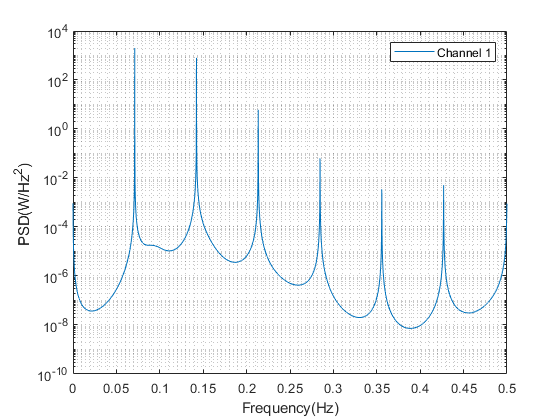

semilogy(f,y_arma);
ylabel('PSD(W/Hz^2) ');
xlabel('Frequency(Hz)');
legend(x_channel_labels)
grid minor;

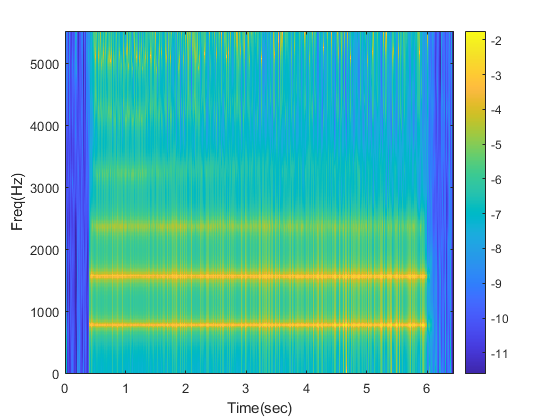

image_y=log10(y_arma_st);
imagesc(x_stax,y_stax,image_y)
caxis([min(min(image_y)) max(max(image_y))]);
xlabel('Time(sec)')
ylabel('Freq(Hz)')
set(gca,'YDir','normal')
colorbar;

### MUSIC PSD

[y_music,f] = spestm_obj.psd_music();
y_music_st=spestm_obj_st.psd_music();

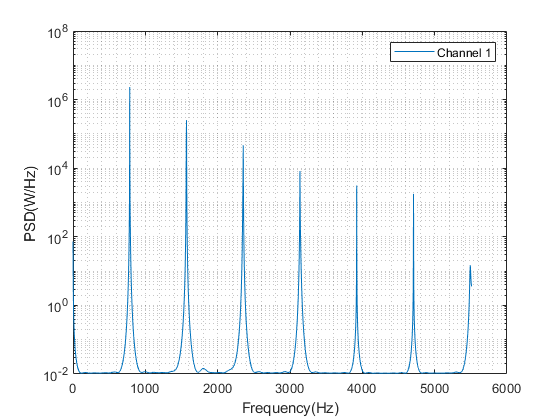

semilogy(f,y_music);
ylabel('PSD(W/Hz) ');
xlabel('Frequency(Hz)');
legend(x_channel_labels)
grid minor;

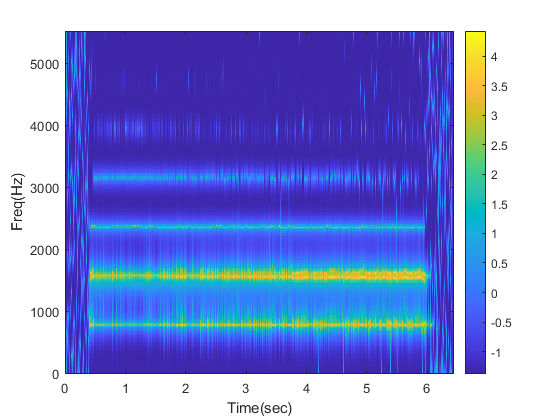

image_y=log10(y_music_st);
imagesc(x_stax,y_stax,image_y)
caxis([min(min(image_y)) max(max(image_y))]);
xlabel('Time(sec)')
ylabel('Freq(Hz)')
set(gca,'YDir','normal')
colorbar;

### Min-Norm PSD

[y_minnorm,f]=spestm_obj.psd_minnorm();
y_minnorm_st=spestm_obj_st.psd_minnorm();

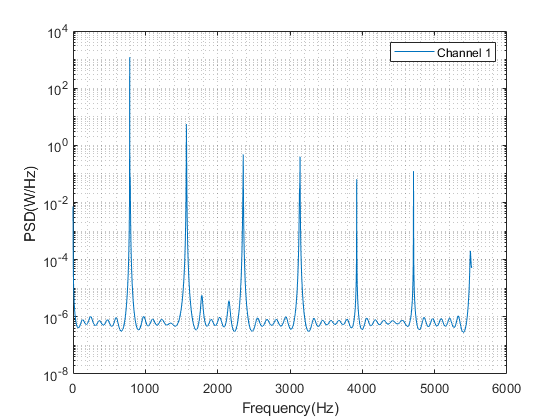

semilogy(f,y_minnorm);
ylabel('PSD(W/Hz) ');
xlabel('Frequency(Hz)');
legend(x_channel_labels)
grid minor;

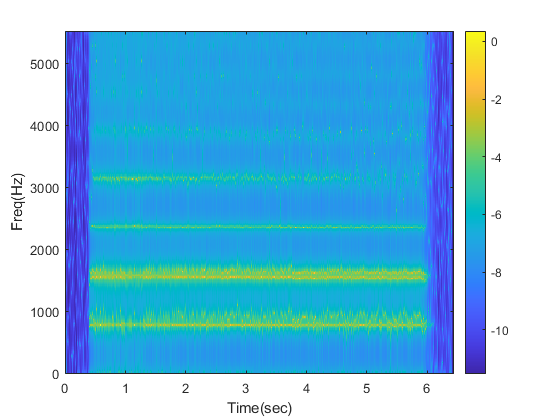

image_y=log10(y_minnorm_st);
imagesc(x_stax,y_stax,image_y)
caxis([min(min(image_y)) max(max(image_y))]);
xlabel('Time(sec)')
ylabel('Freq(Hz)')
set(gca,'YDir','normal')
colorbar;

## Comparison of All PSDs

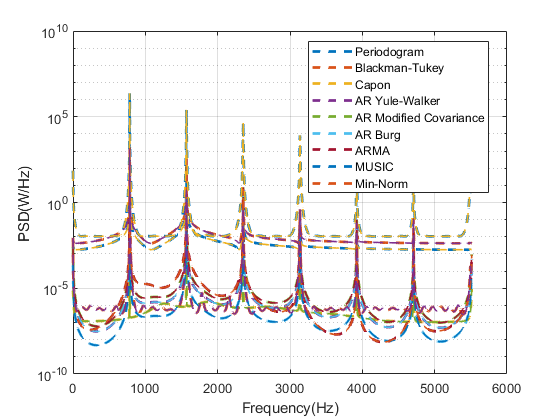

lw=1.2;
sep='--';

semilogy(f,y_per,sep,'linewidth',lw); hold on;
plot(f,y_bt,sep,'linewidth',lw)
plot(f,y_cap,sep,'linewidth',lw)
plot(f,y_aryw,sep,'linewidth',lw)
plot(f,y_armc,sep,'linewidth',lw)
plot(f,y_arburg,sep,'linewidth',lw)
plot(f,y_arma,sep,'linewidth',lw)
plot(f,y_music,sep,'linewidth',lw)
plot(f,y_minnorm,sep,'linewidth',lw)
ylabel('PSD(W/Hz) ');
xlabel('Frequency(Hz)');
legend('Periodogram', 'Blackman-Tukey', 'Capon', 'AR Yule-Walker', 'AR Modified Covariance' ...
    , 'AR Burg', 'ARMA', 'MUSIC', 'Min-Norm','Location','best')
grid on;